# P2. Dinámica Lateral del Vehículo

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 28 Septiembre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta práctica complementaremos el modelo de nuestro monoplaza que ya creamos en la P1, **incluyendo las componentes de la dinámica longitudinal y lateral**, y mantendremos las funciones de control longitudinal definidas en P1.

Para completar esta práctica se necesita conocer la ecuación de la dinámica lateral de un vehículo desarrollada en el Bloque 2 junto con el modelo de bicicleta cinemático y dinámico. 

Al terminar esta práctica deberás ser capaz de:

- Implementar el modelo de bicicleta cinemático (geométrico puro, sin deslizamiento) y el modelo dinámico (fuerzas de neumático con rigidez en deriva) para complementar el modelo longitudinal de P1 con un modelo que capture la dinámica lateral del vehículo. 

- Simular el evento 2 de la FS Driverless conocido como *skidpad*: giro estacionario, de forma simplificada.

- Adquirir datos de telemetría: velocidad de guiñada del vehículo, su aceleración lateral y los ángulos de deriva.

- Comparar los resultados de ambos modelos. 

#### Qué vas a implementar

A) El modelo cinématico (función `pasoCinematico`)

B) El modelo dinámico (función `pasoDinamico`)

### Parametros del vehículo y de la calzada

p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta = 0;      % inclinación de la calzada [rad]

% Define aquí los parámetros necesarios para describir la dinámica lateral
% del vehículo
p.ld = 0.765; % [m] distancia del CG al eje delantero en x
p.lt = 0.765; % [m] distancia del CG al eje trasero en x
p.lyd = 0.600; % [m] distancia del CG a las ruedas del eje delantero en y
p.lyt = 0.600; % [m] distancia del CG a las ruedas del eje trasero en y
% Coordenadas de cada rueda respecto al CG
% Orden: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.Iz = 130; % [kg m^2] inercia de guiñada
p.Cad = 35000; % [N/rad] rigidez deriva delantera
p.Cat = 50000; % [N/rad] rigidez deriva trasero --> vehículo subvirador! 
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.mu_t = 1.5; % rozamiento neumático trasero
p.mu_d = 0.95*p.mu_t; % rozamiento neumático delantero
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];

% Reparto de fuerzas longitudinales
p.drive_w = [0, 0, 0.5, 0.5];
p.brake_w = [0.3,0.3,0.2,0.2];



### Modelo del vehículo

Aquí se debe definir la física del movimiento del vehículo en sentido longitudinal y **lateral**. 

🚧 **Importante**: *En esta práctica definiremos el modelo completo que podrás usar como base para tu proyecto individual.*

Dado el **estado actual del vehículo, fuerza tractiva aplicada, y el ángulo de giro del volante** deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

💣 **OJO!:  **Será necesario compilar primero la geometría del circuito y el controlador. 

% Integración de la dinámica longitudinal y lateral

% u: variable de control = [Fx; delta] 
% z: vector de estados del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada

z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0]; % estado inicial del monoplaza

function z_next = pasoCinematico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    L = p.ld + p.lt;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m; % ecuación del movimiento longitudinal
    vx_next = max(vx + ax*dt,0);

    %% Dinámica lateral [cinemático]
    beta = atan((p.lt/L)*tan(delta)); % ángulo de deriva cinemática
    r = (vx/p.lt)*tan(beta);
    vy = vx*tan(beta);

    % cambio al sistema global
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy; r]; % vector de estados en el siguiente paso temporal

end

function [z_next, tele] = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0,
    % desactivada ahora que el modelo usa atan2

    % Velocidades locales de las cuatro ruedas
    vxw = vx - r.*yw;
    vyw = vy + r.*xw;

    % ángulos de deriva y fuerzas laterales por rueda
    delta_w = [delta, delta, 0, 0];
    alpha_w = delta_w - atan2(vyw,vxw);
    
    % Fuerzas laterales por rueda
    Fyw = p.Caw.*alpha_w;

    %% Definimos límites de adherencia
    Fzd = p.m*p.g*p.lt/L; 
    Fzt = p.m*p.g*p.ld/L; 
    Fzw = [Fzd/2, Fzd/2, Fzt/2, Fzt/2]; % fuerza en z por cada rueda DI, DD, TI, TD

    % Agarre longitudinal
    % Reparto longitudinal por rueda

    if Fx >= 0
        Fxw = Fx .* p.drive_w;
    else
        Fxw = Fx .* p.brake_w;
    end

    % Círculo de límite de adherencia rueda por rueda
    Fmax_w = p.muw .* Fzw; % Capacidad máxima de fuerza por rueda
    Fres_w = hypot(Fxw,Fyw); % Módulo de la fuerza resultante solicitada
    lambda_w = min(ones(1,4),Fmax_w ./ max(Fres_w,eps)); % Factor de saturación

    %Fuerzas efectivas
    Fxw = lambda_w .* Fxw;
    Fyw = lambda_w .* Fyw;

    % Componentes de las fuerzas laterales en el chasis
    Fxw_chasis = Fxw .* cos(delta_w) - Fyw .* sin(delta_w);

    Fyw_chasis = Fxw .* sin(delta_w) + Fyw .* cos(delta_w);

    % Fuerzas y momento resultantes
    SumFx = sum(Fxw_chasis); % Fuerza longitudinal total
    SumFy = sum(Fyw_chasis); % Fuerza lateral total
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Momento de guiñada respecto al CG

    % Telemetria: datos del paso actual, sin modificar las fuerzas ni la dinamica
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_w)) ...
                     - p.yw .* (Fxw .* cos(delta_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % ecuaciones del movimiento 
    ax = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m + vy*r; % ojo no olvidar el acoplamiento de la centripeta 
    ay = SumFy/p.m - vx*r; 
    dr = SumMz/p.Iz;   
   
    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next]; 
end


### Controlador velocidad 

% Controlador PI de velocidad con saturación de fuerza identico a P1
ctrl.v_skid = 5; %[m/s] 5 originalmente 18 km/h , ahora 8 para probar diferencia
ctrl.Kp = 800; 
ctrl.Ki = 200;

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx;
    e_int = e_int + e*dt;

    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % PI
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); % saturación para el cinemático
end


### Geometría del circuito de pruebas

Vamos a simular la prueba del skidpad simplificada, que consistirá en completar 2.5 vueltas a una trayectoría circular de radio constante interior de 15.25 m a través de un carril de 3 m de ancho. El objetivo será completar esta trayectoria en el menor tiempo posible sin salirse del carril. **Únicamente la 2ª vuelta es cronometrada**.  

%% SIMULADOR DE LA PRUEBA DEL SKIDPAD [NO MODIFICAR]
geom.R_in = 15.25/2; % radio interior (conos azules) [m]
geom.R_out = geom.R_in + 3; % radio exterior (conos amarillos; carril de 3m) [m]
geom.R = (geom.R_in + geom.R_out)/2; % radio de la línea central [m]

function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
    N = round(Tmax/dt);  z = z0;  e_int = 0;
    L = p.ld + p.lt;
    delta = atan(L/geom.R); 
    hist.t=zeros(1,N); hist.X=zeros(1,N); hist.Y=zeros(1,N); hist.psi=zeros(1,N);
    hist.vx=zeros(1,N); hist.vy=zeros(1,N); hist.r=zeros(1,N);
    hist.af=zeros(1,N); hist.ar=zeros(1,N);
    % Telemetria nueva, solo para el modelo dinamico de cuatro ruedas
    es4R = strcmp(func2str(modelo), 'pasoDinamico');
    if es4R
        hist.alpha_w = zeros(N,4);
        hist.Fxw = zeros(N,4);
        hist.Fyw = zeros(N,4);
        hist.Fzw = zeros(N,4);
        hist.Mzw = zeros(N,4);
        hist.Mz_long = zeros(1,N);
        hist.Mz_lat = zeros(1,N);
        hist.lambda_w = zeros(N,4);
        hist.Fmax_w = zeros(N,4);
    end
    for k = 1:N
        [Fx, e_int] = controlLongitudinal(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        u = [Fx; delta];
        vx_c = max(z(4), 1.0);
        hist.af(k) = delta - (z(5) + p.ld*z(6))/vx_c;
        hist.ar(k) =       - (z(5) - p.lt*z(6))/vx_c;
        if es4R
            [z, tele] = modelo(z, u, p, dt);
            hist.alpha_w(k,:) = tele.alpha_w;
            hist.Fxw(k,:) = tele.Fxw;
            hist.Fyw(k,:) = tele.Fyw;
            hist.Fzw(k,:) = tele.Fzw;
            hist.Mzw(k,:) = tele.Mzw;
            hist.Mz_long(k) = tele.Mz_long;
            hist.Mz_lat(k) = tele.Mz_lat;
            hist.lambda_w(k,:) = tele.lambda_w;
            hist.Fmax_w(k,:) = tele.Fmax_w;
        else
            z = modelo(z, u, p, dt);
        end
        hist.t(k)=(k-1)*dt; hist.X(k)=z(1); hist.Y(k)=z(2); hist.psi(k)=z(3);
        hist.vx(k)=z(4); hist.vy(k)=z(5); hist.r(k)=z(6);
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));                  
    hist.tVueltas = zeros(1, max(0, max(nV)));        
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end

function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: 2ª vuelta = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: no completa 2 vueltas en Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (¡sale del carril!)'); end
    fprintf('\n');
end

### Simulación

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % ~2.5 vueltas (la 2ª es la cronometrada)

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6));

### Resultados 

Deberíamos observar como el monoplaza que sigue el modelo cinemático traza un cículo de radio ~9m (geometría pura) mientras que el modelo dinámico traza un radio ligeramente mayor debido al subviraje (ligero subviraje debido a angulos de deriva pequeños; determinados por la rigidez de deriva de ambos ejes). 

fprintf('Ackermann R = %.2f m  (delta = %.2f deg)\n', geom.R, atan((p.ld+p.lt)/geom.R)*180/pi);

Ackermann R = 9.12 m  (delta = 9.52 deg)


fprintf('Radio medido — cinemático: %.2f m | dinámico: %.2f m\n', Rcin, Rdin);

Radio medido — cinemático: 9.13 m | dinámico: 9.39 m


fprintf('Subviraje: el dinámico traza %.1f%% más radio.\n', 100*(Rdin-Rcin)/Rcin);

Subviraje: el dinámico traza 2.9% más radio.


fprintf('Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):\n');

Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):


informarVueltas('cinemático', histCin);

   cinemático: 2ª vuelta = 11.47 s


informarVueltas('dinámico  ', histDin);

   dinámico  : 2ª vuelta = 11.80 s


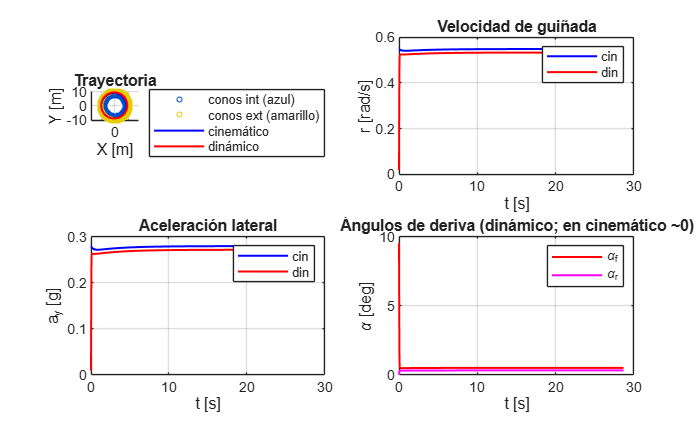

figure('Name','L2 · Skidpad','Color','w');

subplot(2,2,1); hold on; axis equal; grid on;  
  th = linspace(0,2*pi,200);
  plot(geom.R_in*cos(th), geom.R_in*sin(th), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(geom.R_out*cos(th),geom.R_out*sin(th),'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(histCin.X, histCin.Y, 'b-','LineWidth',1.2);
  plot(histDin.X, histDin.Y, 'r-','LineWidth',1.2);
  legend('conos int (azul)','conos ext (amarillo)','cinemático','dinámico','Location','bestoutside');
  title('Trayectoria'); xlabel('X [m]'); ylabel('Y [m]');

subplot(2,2,2);   
  plot(histCin.t,histCin.r,'b', histDin.t,histDin.r,'r','LineWidth',1.2);
  ylabel('r [rad/s]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Velocidad de guiñada');

subplot(2,2,3);   
  plot(histCin.t, histCin.vx.*histCin.r/9.81,'b', ...
       histDin.t, histDin.vx.*histDin.r/9.81,'r','LineWidth',1.2);
  ylabel('a_y [g]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Aceleración lateral');

subplot(2,2,4);   
  plot(histDin.t, histDin.af*180/pi,'r', histDin.t, histDin.ar*180/pi,'m','LineWidth',1.2);
  ylabel('\alpha [deg]'); xlabel('t [s]'); grid on; legend('\alpha_f','\alpha_r');
  title('Ángulos de deriva (dinámico; en cinemático ~0)');

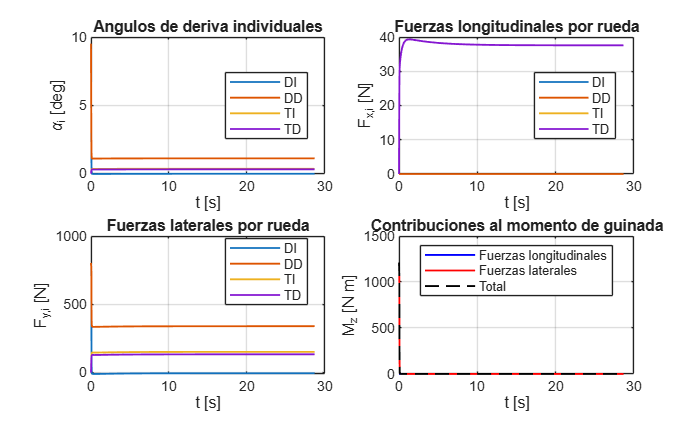


%% NUEVA FIGURA: telemetria del modelo dinamico de cuatro ruedas
% Orden de ruedas: DI, DD, TI, TD. No modifica la simulacion original.
figure('Name','Modelo 4 ruedas - Telemetria','Color','w');
nombres = {'DI','DD','TI','TD'};

subplot(2,2,1);
plot(histDin.t, rad2deg(histDin.alpha_w), 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('\alpha_i [deg]');
title('Angulos de deriva individuales'); legend(nombres,'Location','best');

subplot(2,2,2);
plot(histDin.t, histDin.Fxw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{x,i} [N]');
title('Fuerzas longitudinales por rueda'); legend(nombres,'Location','best');

subplot(2,2,3);
plot(histDin.t, histDin.Fyw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{y,i} [N]');
title('Fuerzas laterales por rueda'); legend(nombres,'Location','best');

subplot(2,2,4);
plot(histDin.t, histDin.Mz_long, 'b', ...
     histDin.t, histDin.Mz_lat, 'r', ...
     histDin.t, histDin.Mz_long + histDin.Mz_lat, 'k--', 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('M_z [N m]');
title('Contribuciones al momento de guinada');
legend('Fuerzas longitudinales','Fuerzas laterales','Total','Location','best');

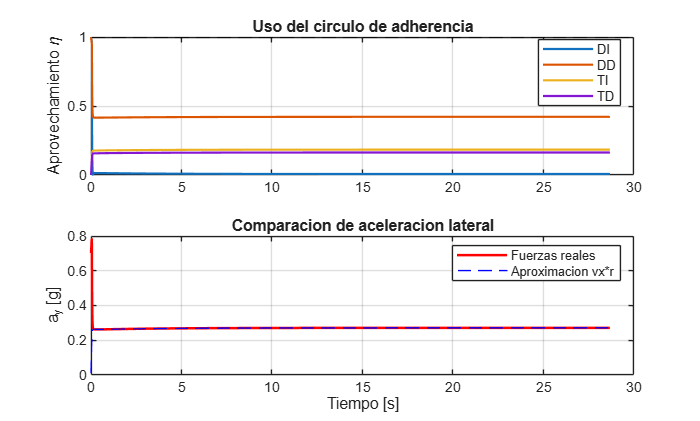

%% Comprobacion del circulo de adherencia

t = histDin.t(:);
Fx = histDin.Fxw;
Fy = histDin.Fyw;
Fz = histDin.Fzw;

% Aprovechamiento de adherencia por rueda
Fmax = Fz .* p.muw;
eta = hypot(Fx, Fy) ./ Fmax;

% Aceleracion lateral a partir de las fuerzas
delta = atan((p.ld + p.lt)/geom.R);
delta_w = [delta, delta, 0, 0];

Fy_chasis = Fx.*sin(delta_w) + Fy.*cos(delta_w);
ay_real = sum(Fy_chasis, 2)/(p.m*p.g);

% Graficas
figure('Color','w');

subplot(2,1,1)
plot(t, eta, 'LineWidth',1.3)
yline(1,'k--','Limite adherencia');
grid on;
ylabel('Aprovechamiento \eta');
legend('DI','DD','TI','TD','Location','best');
title('Uso del circulo de adherencia');

subplot(2,1,2)
plot(t, ay_real, 'r','LineWidth',1.5)
hold on;
plot(t, histDin.vx(:).*histDin.r(:)/p.g, 'b--');
grid on;
xlabel('Tiempo [s]');
ylabel('a_y [g]');
legend('Fuerzas reales','Aproximacion vx*r');
title('Comparacion de aceleracion lateral');


% Comprobacion numerica
fprintf('Aprovechamiento maximo por rueda:\n');

Aprovechamiento maximo por rueda:


disp(max(eta,[],1));

    1.0000    1.0000    0.1839    0.1632




fprintf('Aceleracion lateral maxima: %.3f g\n', ...
    max(abs(ay_real)));

Aceleracion lateral maxima: 0.784 g


fprintf('\n--- Resumen modelo 4 ruedas ---\n');


--- Resumen modelo 4 ruedas ---


fprintf('Velocidad final: %.2f m/s\n', histDin.vx(end));

Velocidad final: 5.00 m/s


fprintf('Guiñada final: %.3f rad/s\n', histDin.r(end));

Guiñada final: 0.532 rad/s


fprintf('Max |deriva| por rueda [deg]: ');

Max |deriva| por rueda [deg]: 

fprintf('%.2f ', max(abs(rad2deg(histDin.alpha_w)),[],1));

9.52 9.52 0.35 0.30 

fprintf('\nMax |Fx| por rueda [N]: ');


Max |Fx| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fxw),[],1));

0.0 0.0 39.3 39.3 

fprintf('\nMax |Fy| por rueda [N]: ');


Max |Fy| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fyw),[],1));

803.8 803.8 151.0 132.8 

fprintf('\n');


Como vemos el modelo cinemático traza un círculo de radio constante al no tener deriva, mientras que el modelo dinámico traza un círculo ligeramente mayor con el mismo ángulo de giro del volante debido al subviraje del vehículo. Ambos experimentan una fuerza lateral de aproximadamente 0.55g. 

⚡ En Formula Student, el tiempo en el skidpad mide la aceleración lateral máxima del monoplaza. En la industria del automóvil, los ensayos de radio constante sirven además para medir el **gradiente de subviraje**.